%In this file we will generate the DPD theoretical output


## Part one: with (5,1,1) (Orthogonal)


disp("Order 5, Memory depth 1, Orthogonal:")

Order 5, Memory depth 1, Orthogonal:


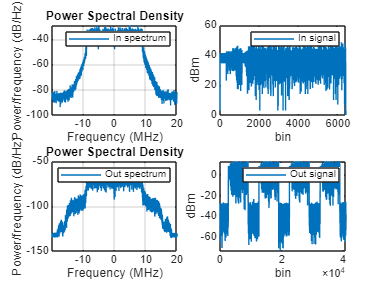

D = 22520

z_dc_lenght = 6407

D1 = 28

delta_freq = 9.6583e+03

phase_shift = 2.3328

aligned_phase_shift = 0.7290

delta_freq = 9.6583e+03

phase_shift = 2.2619

aligned_phase_shift = 0.0221

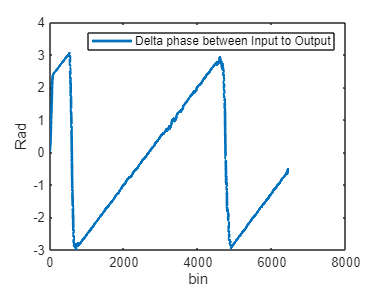

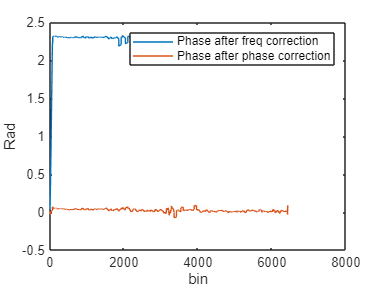

D2 = -1

orthogonal = 1

Condition_number = 12.1369

DPD_coef_Inverse = 1.0e+02 *

   2.3537 + 0.1068i
   0.1743 + 0.0329i
   0.0162 + 0.0216i
  -0.0009 + 0.0154i
   0.0061 + 0.0022i
   0.0432 - 0.0425i
   0.0551 + 0.0054i
   0.0164 + 0.0103i
   0.0137 + 0.0121i
   0.0137 + 0.0026i


orthogonal = 1

ans = 75.7407

orthogonal = 1

Condition_number = 15.1774

amp_coef = 1.0e+02 *

   2.4046 - 0.1165i
  -0.1732 - 0.0251i
   0.0109 - 0.0183i
  -0.0052 - 0.0080i
  -0.0088 + 0.0045i
  -0.0361 + 0.0481i
  -0.0459 - 0.0081i
  -0.0072 - 0.0108i
  -0.0164 - 0.0085i
  -0.0090 + 0.0020i


orthogonal = 1

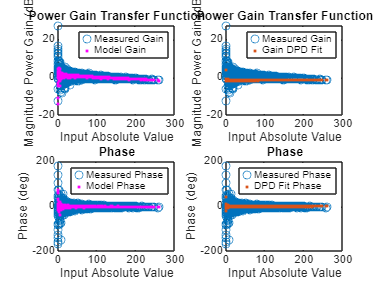

n =     1.0187   -0.0003


NSME_no_dpd = -21.3595

n =     0.8451    0.0009


NSME_with_dpd = -50.9278

NMSE = -50.9278

Cond_num = 15.1774

%Run_DPD_Algorithm(order, memory_depth, isOrthogonal)
[a,b,c1] = Run_DPD_Algorithm(5,1,1);

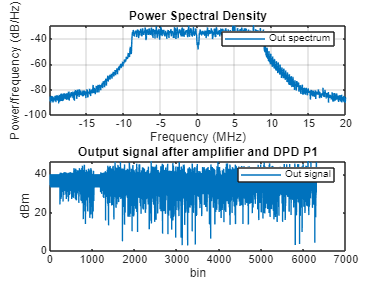


figure;

subplot(2,1,1)

% Spectrum of signal after DPD with orthogonal polyonmials 
Fs = 40e+6;
pwelch(c1,[],[],[],Fs,'centered')
legend('Out spectrum')
subplot(2,1,2)
c_pow = 10*log10(abs(c1).^2);

% Signal after amp and DPD in dBm with orthogonal polyonmials 
plot(c_pow(100:6400))
xlabel('bin')
ylabel('dBm')
title('Output signal after amplifier and DPD P1')
legend('Out signal')

## Part 2: with (5,1,0) (Non orthogonal)

disp("------------------------------------------------------------")

------------------------------------------------------------


disp("Order 5, Memory depth 1, Not orthogonal:")

Order 5, Memory depth 1, Not orthogonal:


D = 22520

z_dc_lenght = 6407

D1 = 28

delta_freq = 9.6583e+03

phase_shift = 2.3328

aligned_phase_shift = 0.7290

delta_freq = 9.6583e+03

phase_shift = 2.2619

aligned_phase_shift = 0.0221

D2 = -1

orthogonal = 0

Condition_number = 1.2770e+10

DPD_coef_Inverse =    0.9089 - 0.0002i
  -0.0008 + 0.0005i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i


orthogonal = 0

ans = 92.1714

orthogonal = 0

Condition_number = 1.7108e+10

amp_coef =    1.1203 + 0.0077i
  -0.0001 - 0.0011i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i


orthogonal = 0

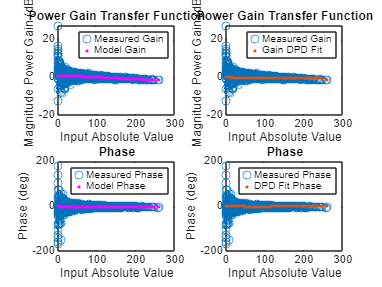

n =     1.0187   -0.0003


NSME_no_dpd = -21.3595

n =     0.9977   -0.0006


NSME_with_dpd = -43.5296

NMSE = -43.5296

Cond_num = 1.7108e+10

%Run_DPD_Algorithm(order, memory_depth, isOrthogonal)
[a,b,c2] = Run_DPD_Algorithm(5,1,0);

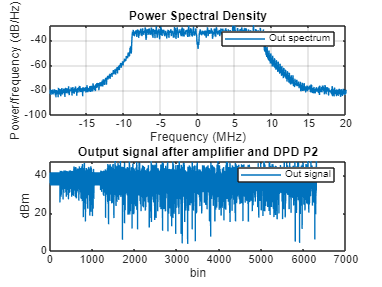


figure;

subplot(2,1,1)

% Spectrum of signal after DPD without orthogonal polyonmials 
Fs = 40e+6;
pwelch(c2,[],[],[],Fs,'centered')
legend('Out spectrum')
subplot(2,1,2)
c_pow = 10*log10(abs(c2).^2);

% Signal after amp and DPD in dBm without orthogonal polyonmials 
plot(c_pow(100:6400))
xlabel('bin')
ylabel('dBm')
title('Output signal after amplifier and DPD P2')
legend('Out signal')

## Part 3 with (2,1,1) (Orthogonal, smaller order)

disp("------------------------------------------------------------")

------------------------------------------------------------


disp("Order 2, Memory depth 1, Orthogonal:")

Order 2, Memory depth 1, Orthogonal:


D = 22520

z_dc_lenght = 6407

D1 = 28

delta_freq = 9.6583e+03

phase_shift = 2.3328

aligned_phase_shift = 0.7290

delta_freq = 9.6583e+03

phase_shift = 2.2619

aligned_phase_shift = 0.0221

D2 = -1

orthogonal = 1

Condition_number = 5.3956

DPD_coef_Inverse = 1.0e+02 *

   2.3411 + 0.0924i
   0.1605 + 0.0118i
   0.0372 - 0.0476i
   0.0447 - 0.0043i


orthogonal = 1

ans = 75.6963

orthogonal = 1

Condition_number = 6.7016

amp_coef = 1.0e+02 *

   2.3884 - 0.1007i
  -0.1913 - 0.0033i
  -0.0408 + 0.0548i
  -0.0460 + 0.0031i


orthogonal = 1

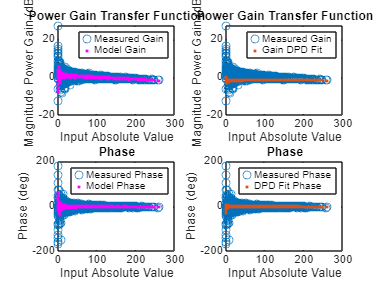

n =     1.0187   -0.0003


NSME_no_dpd = -21.3595

n =     0.8616   -0.0170


NSME_with_dpd = -42.3797

NMSE = -42.3797

Cond_num = 6.7016


%Run_DPD_Algorithm(order, memory_depth, isOrthogonal)
[a,b,c3] = Run_DPD_Algorithm(2,1,1);

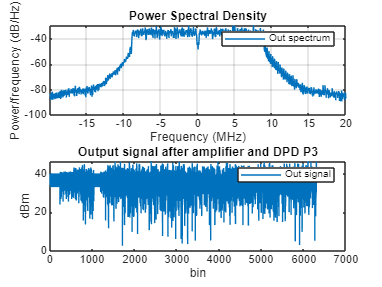


figure;

subplot(2,1,1)

% Spectrum of signal after DPD without orthogonal polyonmials 
Fs = 40e+6;
pwelch(c3,[],[],[],Fs,'centered')
legend('Out spectrum')
subplot(2,1,2)
c_pow = 10*log10(abs(c3).^2);

% Signal after amp and DPD in dBm without orthogonal polyonmials 
plot(c_pow(100:6400))
xlabel('bin')
ylabel('dBm')
title('Output signal after amplifier and DPD P3')
legend('Out signal')

## Part 4 with (2,1,0) (Non orthogonal, smaller order)

disp("------------------------------------------------------------")

------------------------------------------------------------


disp("Order 2, Memory depth 1, Not orthogonal:")

Order 2, Memory depth 1, Not orthogonal:


D = 22520

z_dc_lenght = 6407

D1 = 28

delta_freq = 9.6583e+03

phase_shift = 2.3328

aligned_phase_shift = 0.7290

delta_freq = 9.6583e+03

phase_shift = 2.2619

aligned_phase_shift = 0.0221

D2 = -1

orthogonal = 0

Condition_number = 400.2463

DPD_coef_Inverse =    0.8348 + 0.0134i
   0.0014 + 0.0001i


orthogonal = 0

ans = 92.0188

orthogonal = 0

Condition_number = 381.1204

amp_coef =    1.1399 - 0.0213i
  -0.0012 - 0.0000i


orthogonal = 0

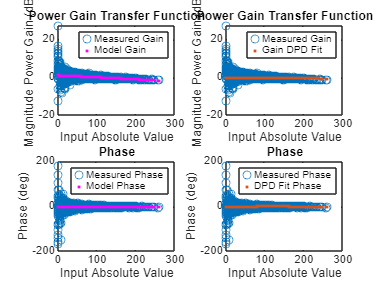

n =     1.0187   -0.0003


NSME_no_dpd = -21.3595

n =     0.9964   -0.0006


NSME_with_dpd = -40.0064

NMSE = -40.0064

Cond_num = 381.1204


%Run_DPD_Algorithm(order, memory_depth, isOrthogonal)
[a,b,c4] = Run_DPD_Algorithm(2,1,0);

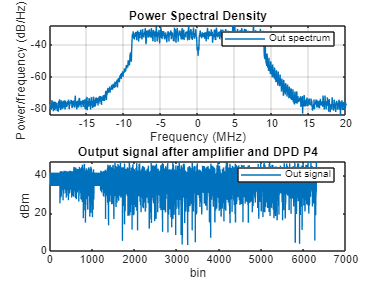


figure;

subplot(2,1,1)

% Spectrum of signal after DPD without orthogonal polyonmials 
Fs = 40e+6;
pwelch(c4,[],[],[],Fs,'centered')
legend('Out spectrum')
subplot(2,1,2)
c_pow = 10*log10(abs(c4).^2);

% Signal after amp and DPD in dBm without orthogonal polyonmials 
plot(c_pow(100:6400))
xlabel('bin')
ylabel('dBm')
title('Output signal after amplifier and DPD P4')
legend('Out signal')